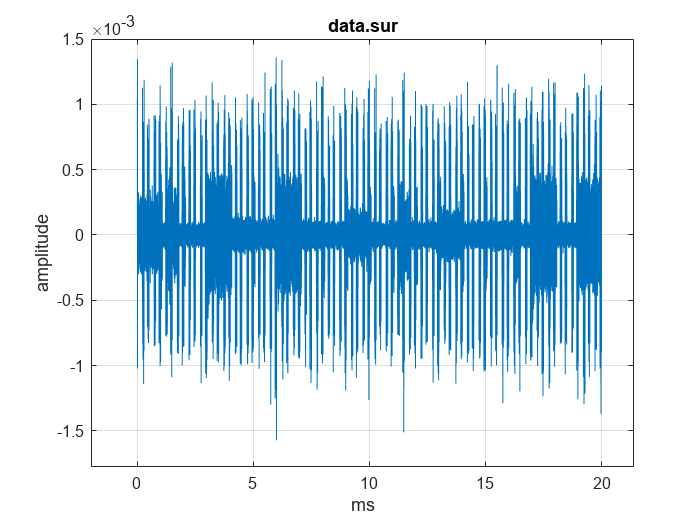

idx_start_time =1;
data = load(sprintf('./data/data_%d.mat',idx_start_time)); % load data
sur = data.seq_sur;
ref = data.seq_ref;
N = length(data.seq_sur);
plot_num = 0.02*data.f_s;
sur_plot = data.seq_sur(1,1:plot_num);
ref_plot = data.seq_ref(1,1:plot_num);
iPlot('plot', linspace(0,20,plot_num), real(sur_plot), 'data.sur', 'ms', 'amplitude');

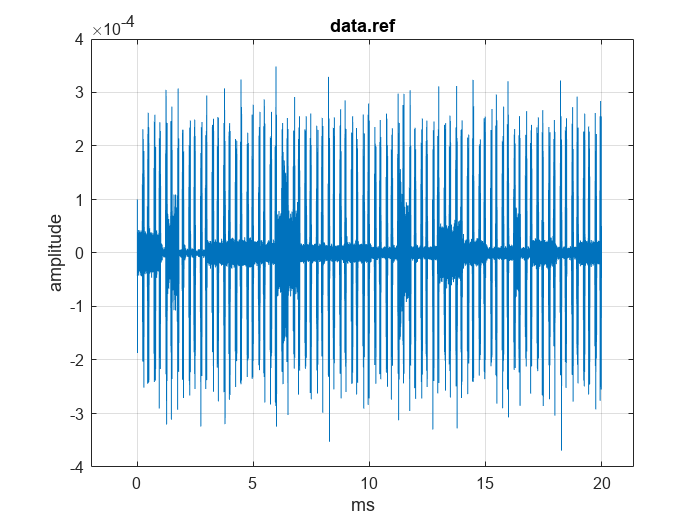

iPlot('plot', linspace(0,20,plot_num), real(ref_plot), 'data.ref', 'ms', 'amplitude');

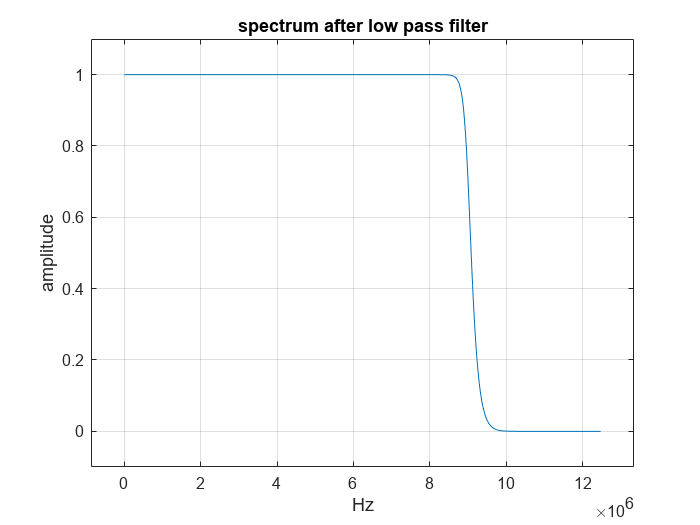

f_band = 9e6;
[b,a] = butter(20,f_band/(data.f_s/2));
[h,f] = freqz(b,a,512,data.f_s);
iPlot('plot', f, abs(h), 'spectrum after low pass filter', 'Hz', 'amplitude');

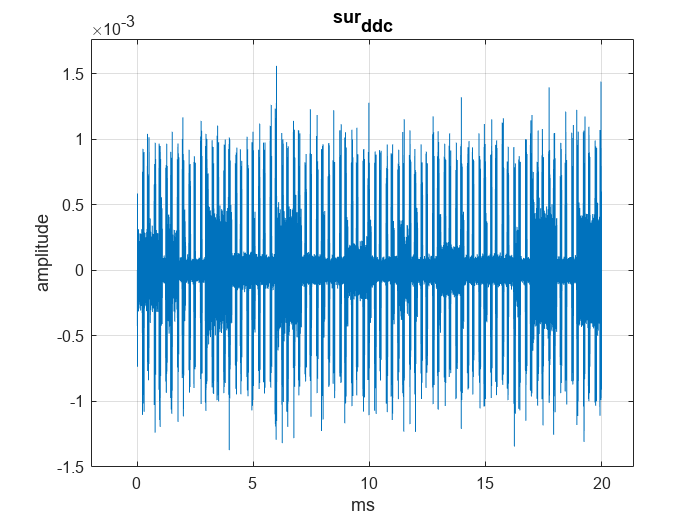

f_ddc = -3e6;
sur_ddc = sur.*exp(-1i*2*pi*f_ddc*(0:N-1)/data.f_s);
ref_ddc = ref.*exp(-1i*2*pi*f_ddc*(0:N-1)/data.f_s);
sur_plot = sur_ddc(1,1:plot_num);
ref_plot = ref_ddc(1,1:plot_num);
iPlot('plot', linspace(0,20,plot_num), real(sur_plot), 'sur_{ddc}', 'ms', 'amplitude');

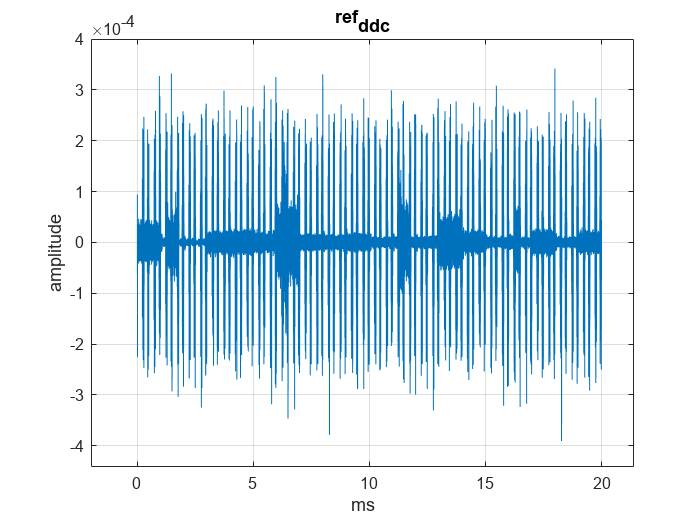

iPlot('plot', linspace(0,20,plot_num), real(ref_plot), 'ref_{ddc}', 'ms', 'amplitude');

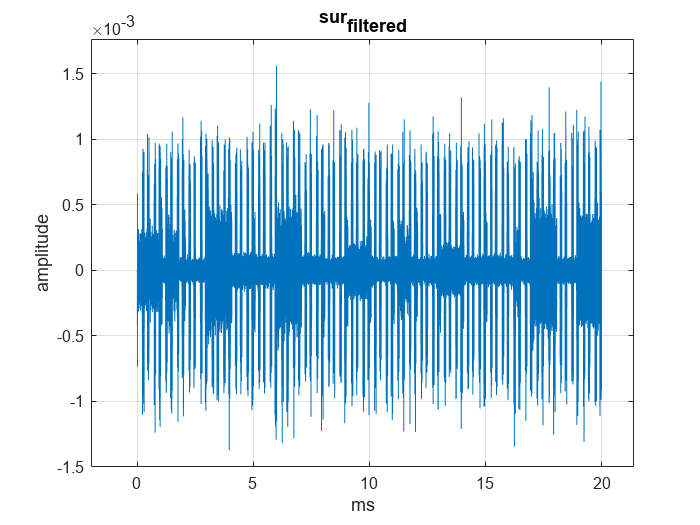

sur_out = filter(b,a,sur_ddc);
ref_out = filter(b,a,ref_ddc);
sur_plot = sur_ddc(1,1:plot_num);
ref_plot = ref_ddc(1,1:plot_num);
iPlot('plot', linspace(0,20,plot_num), real(sur_plot), 'sur_{filtered}', 'ms', 'amplitude');

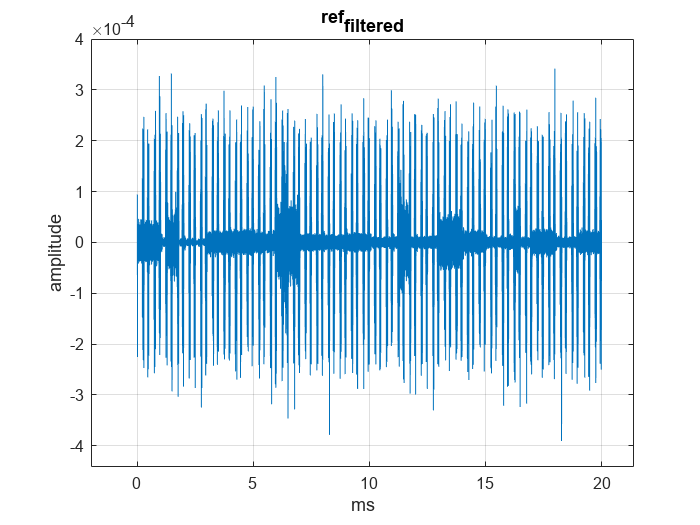

iPlot('plot', linspace(0,20,plot_num), real(ref_plot), 'ref_{filtered}', 'ms', 'amplitude');

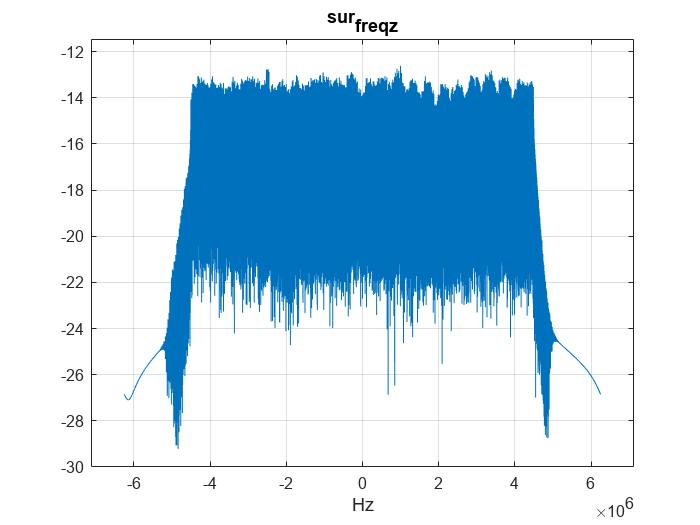

sur = fftshift(fft(sur_out)./N);
ref = fftshift(fft(ref_out)./N);
iPlot('plot', -N/2:N-N/2-1, log(abs(sur)), 'sur_{freqz}', 'Hz', '');

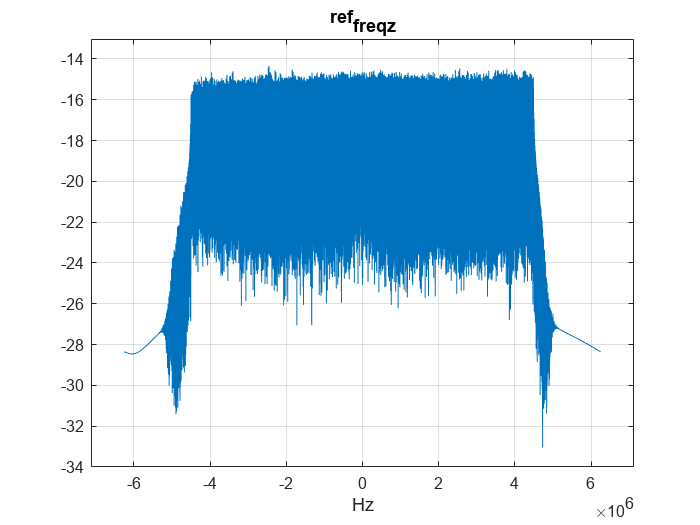

iPlot('plot', -N/2:N-N/2-1, log(abs(ref)), 'ref_{freqz}', 'Hz', '');

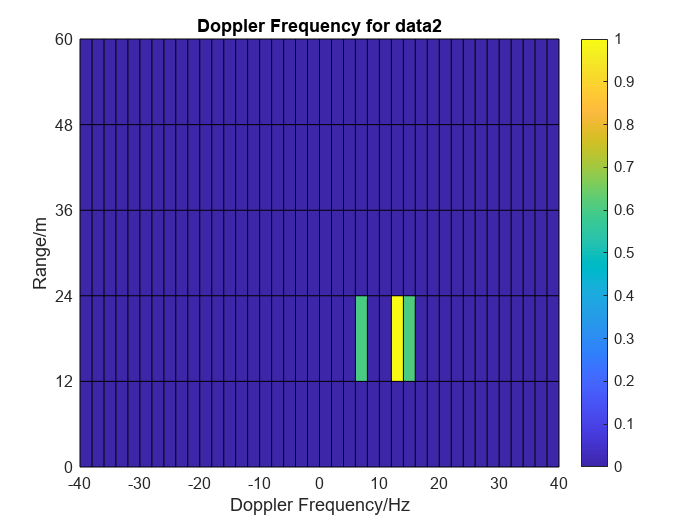

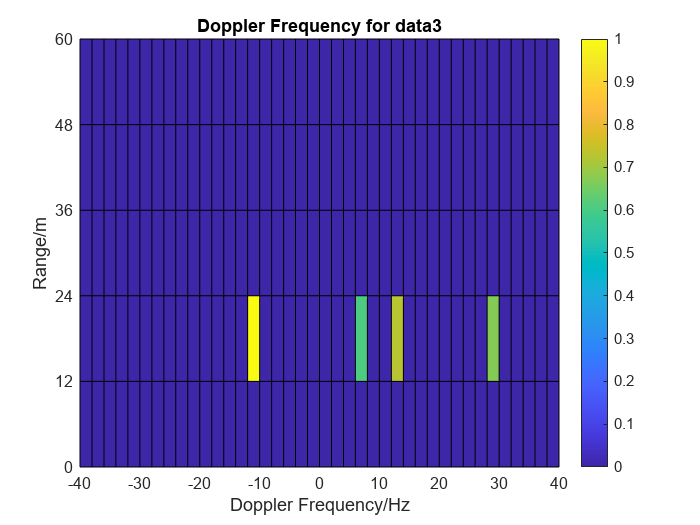

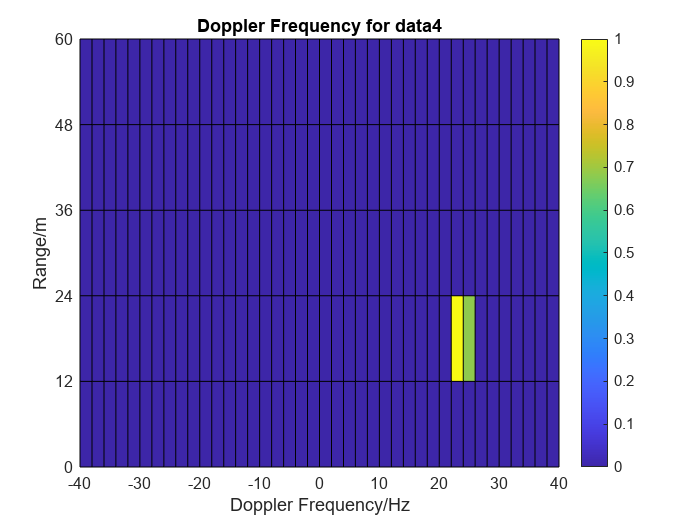

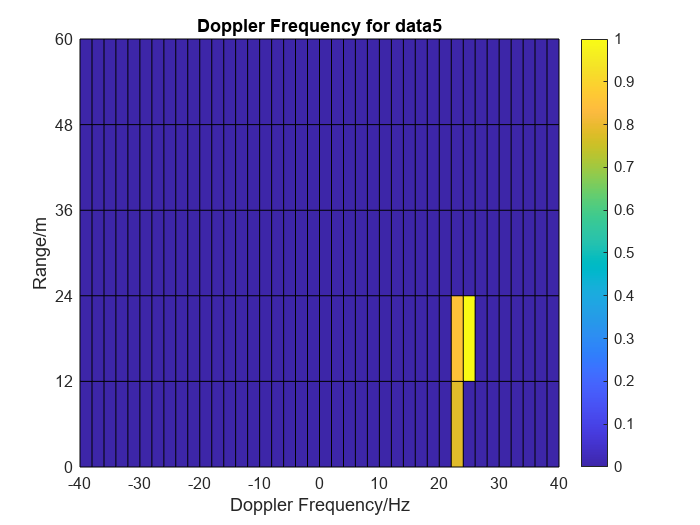

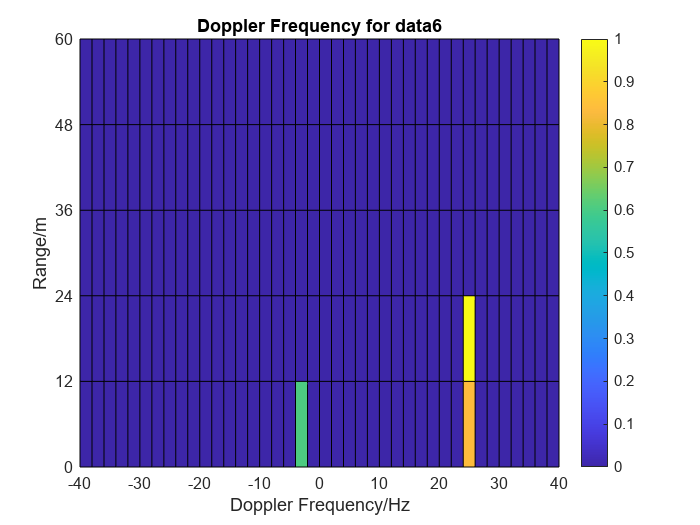

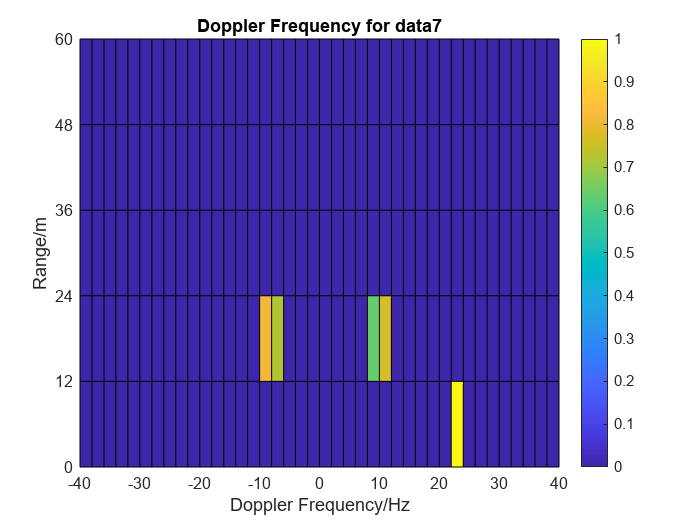

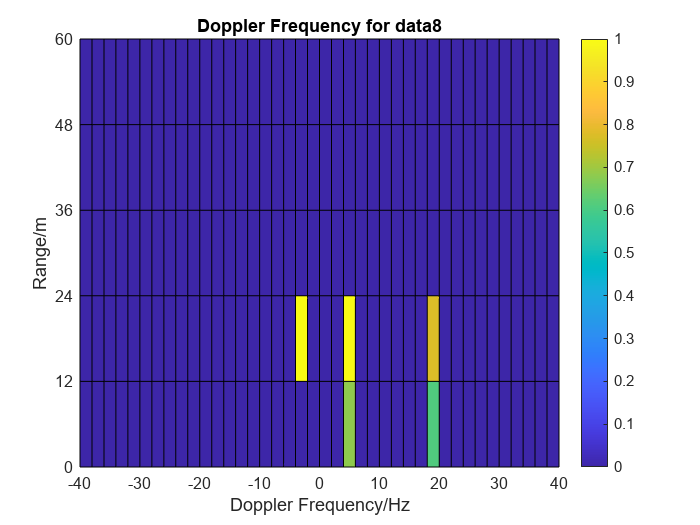

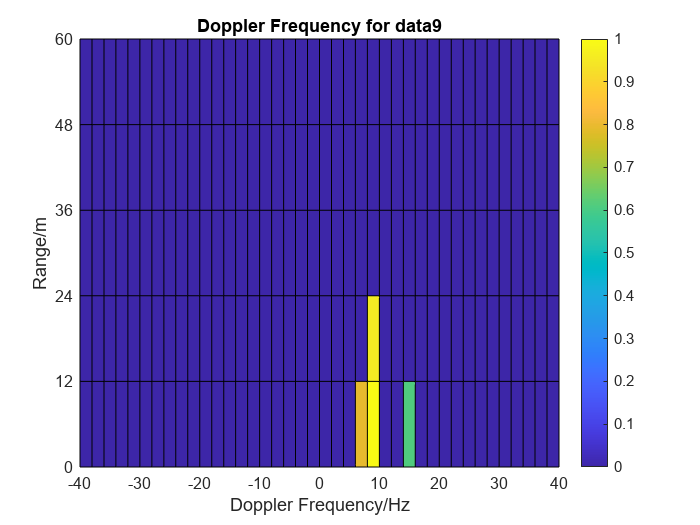

time_doppler_frequency = range_doppler_frequency();

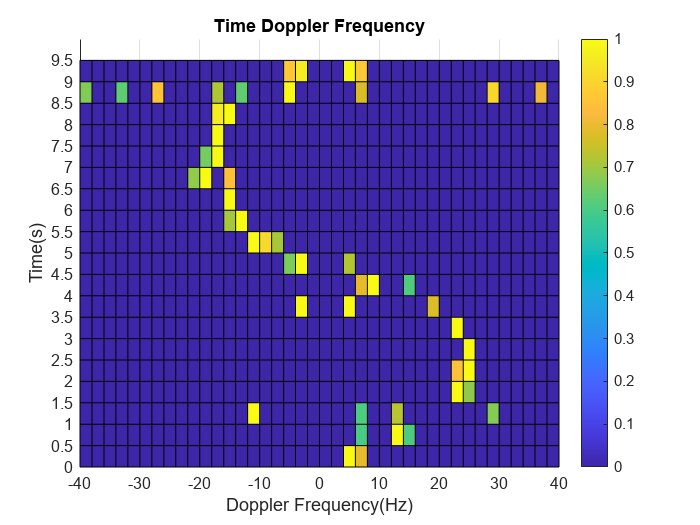

% Draw Time Doppler Frequency Image
n_time = 0:0.5:9.5;
fd = -40:2:40;
[mesh_fd,mesh_time] = meshgrid(fd, n_time);
figure;
surf(mesh_fd, mesh_time, time_doppler_frequency);
view(2);
title('Time Doppler Frequency');
xlabel('Doppler Frequency(Hz)'), ylabel('Time(s)');
colorbar;
yticks(0:0.5:9.5);
saveas(gca, sprintf('time_doppler_frequency.png'));

function for task2

function time_doppler_frequency = range_doppler_frequency()
    time_doppler_frequency = [];
    n_tau = 0:5;
    fd = -40:2:40;
    for n = 1:20
        data = load(sprintf('./data/data_%d.mat',n));
        sur = data.seq_sur;
        ref = data.seq_ref;
        N = length(data.seq_sur);
        f_band = 9e6;
        [b,a] = butter(20,f_band/(data.f_s/2));
        %[h,f] = freqz(b,a,512,data.f_s);
        f_ddc = -3e6;
        sur_ddc = sur.*exp(-1i*2*pi*f_ddc*(0:N-1)/data.f_s);
        ref_ddc = ref.*exp(-1i*2*pi*f_ddc*(0:N-1)/data.f_s);
        sur_out = filter(b,a,sur_ddc);
        ref_out = filter(b,a,ref_ddc);
        results = zeros([length(n_tau), length(fd)]);
        for i = 1:length(n_tau)
            for j = 1:length(fd)
                ref_r = [zeros(1,i - 1), ref_out];
                ref_r = ref_r(1:125e5);
                results(i,j) = ambiguity(sur_out, ref_r, fd(j));
            end
        end
        results = abs(results);
        n_tau = 0:12:60;
        [x,y] = meshgrid(fd, n_tau);
        results = results/max(max(results));
        results(results < 0.6) = 0;
        figure;
        surf(x,y,results);
        view(2);
        title(['Doppler Frequency for data', num2str(n)]);
        xlabel('Doppler Frequency/Hz'), ylabel('Range/m');
        colorbar;
        yticks(0:12:60);yticklabels({'0','12','24','36','48','60'});
        saveas(gca, sprintf('task2/data%d.png', n));

        [row,~] = find(results==max(max(results)));
        time_doppler_frequency(n, :) = results(row, :);
    end
end

ambiguity function

function cor = ambiguity(sur, ref, f)
    Ts = 1/25000000;
    nn = 1:125e5;
    cor = sum(conj(ref).*sur.*exp(-1j*2*pi*nn*Ts*f));
end